**EPFL Spacecraft Team - CHESS Mission Design**

Arnaud Muller & Antoine Clout

Autumn 2020

clc
clear
close all

Read TUDAT propagation results

if (~exist('AOP_Optimisation_Results')) %#ok<*EXIST>
    AOP_Optimisation_Results= importdata('AOP_Optimisation_Results.dat');
    AOPValues= importdata('AOP_Optimisation_AOPValues.dat');
end
Epochs=AOP_Optimisation_Results(:,1);
Time=Epochs-Epochs(1);
Timestep=Time(2);
[nb_of_epochs,tmp]=size(AOP_Optimisation_Results);
nb_AOP=tmp-1;
clear tmp

Compute maximum eclipse duration for each spacecraft

maxEclipse=zeros(nb_AOP,1);
for i=1:nb_AOP
    compteur = 0;
    Eclipses = zeros(nb_of_epochs,1);
    for k=1:nb_of_epochs
        if AOP_Optimisation_Results(k,i+1) > 0
            Eclipses(k) = compteur;
            compteur = 0;
        else
            compteur = compteur +1;
        end
    end
    if sum(Eclipses(end-1,1)==0)
        Eclipses(k) =0;
    else
        Eclipses(k) = compteur;
    end
    clear compteur
    Eclipses=Timestep*Eclipses(Eclipses > 0);
    if isempty(max(Eclipses))
        maxEclipse(i)=0;
    else
        maxEclipse(i)=max(Eclipses);
    end
end

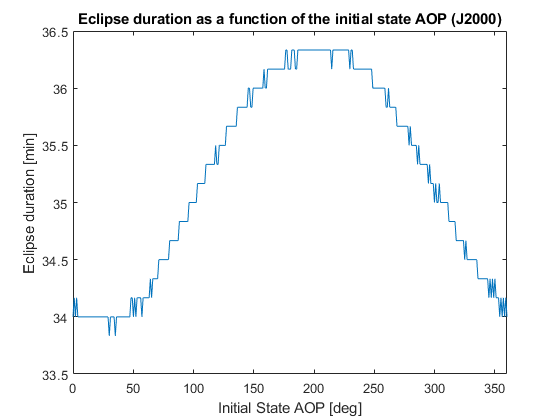

figure
plot(AOPValues,maxEclipse/60)
xlim([0 360])
xlabel('Initial State AOP [deg]')
ylabel('Eclipse duration [min]')
title('Eclipse duration as a function of the initial state AOP (J2000)')